## Open and Plot Intensity Histogram over entire image

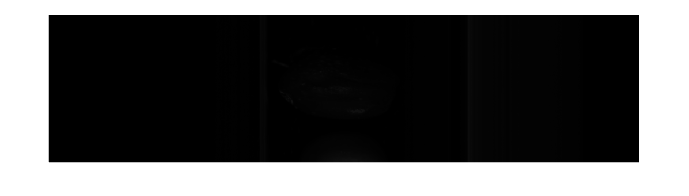

img_raw = imread("test_images/apples_images/Image_77.tiff");
[height, width] = size(img_raw);
imshow(img_raw)

fprintf("Height: %d px\nWidth %d px\n", height, width);

Height: 256 px
Width 1024 px


figure('Name', 'Istogramma Intensità');
histogram(img_raw(:), 512);
title('Intensità SWIR');
xlabel('Intensità [a.u.]');
ylabel('Pixel count');
pause(3);
close;

disp("Basic Statistics of the Image");

Basic Statistics of the Image


min_val = min(img_raw(:));
max_val = max(img_raw(:));
mean_val = mean(img_raw(:));
std_val = std(double(img_raw(:)));
fprintf("Min: %d, Max: %d, Mean: %.2f, Std: %.2f\n", ...
    min_val, max_val, mean_val, std_val);

Min: 0, Max: 4095, Mean: 387.03, Std: 509.92


## Goals of the Analysis

% Finding the ROI of the image:
% 1. find ROIx: 
%       ✅ - extract boundaries for 1 single horiz. stripe 
%       ✅ - average over all horizontal stripes width boundaries ...
%         for ca.100px at I>=2000
% 2. find ROIy: height boundaries for same parameters
%       - extract fpr 1
%       - average over all vertical stripes
% 3. found ROI=(ROIx,ROIy) for 1 image
% 4. repeat for N images

## 1.1 Finding ROIx for one single LINE (1x1024)

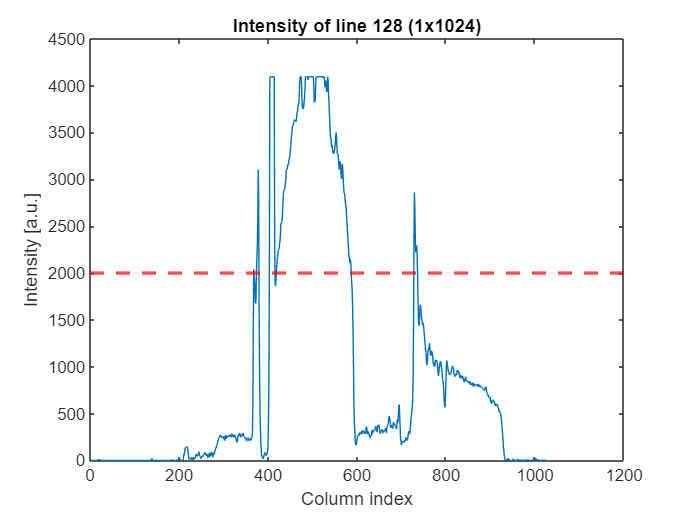

img_raw = imread("test_images/apples_images/Image_70.tiff");
row_idx = round(size(img_raw,1) / 2); % for instance, the central line
line = img_raw(row_idx, :);  

figure;
plot(line);
yline(2000, 'r--', 'LineWidth',2);
xlabel('Column index'); ylabel('Intensity [a.u.]');
title(sprintf('Intensity of line %d (1x%d)', row_idx, length(line)));


thr_apple = 2000; % a.u.
min_length = 100; % px
mask_overthr = line >= thr_apple;
disp(mask_overthr);

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


inside = false;
left_px = NaN;
right_px = NaN;
length_counter = 0;

% LOOP over one line
for i = 1:length(line)
    if mask_overthr(i)
        if ~inside
            % Entering ROIx if intensity>threshold
            inside = true;
            length_counter = 1;
            temp_left = i;
        else
            length_counter = length_counter + 1;
        end
    else
        if inside
            % Exit ROIx
            if length_counter >= min_length
                left_px = temp_left;
                right_px = i - 1;  % previous px is still valid
                break; % ignoring other regions, just the first
            end
            % Reset if region too short
            inside = false;
            length_counter = 0;
        end
    end
end

if ~isnan(left_px)
    fprintf("✅ ROIx found:\nLeft px: %d\nRight px: %d\n", left_px, right_px);
else
    fprintf("❌ No region found over threshold %d for at least %d consectuive pixels.\n", thr_apple, min_length);
end

✅ ROIx found:
Left px: 419
Right px: 587


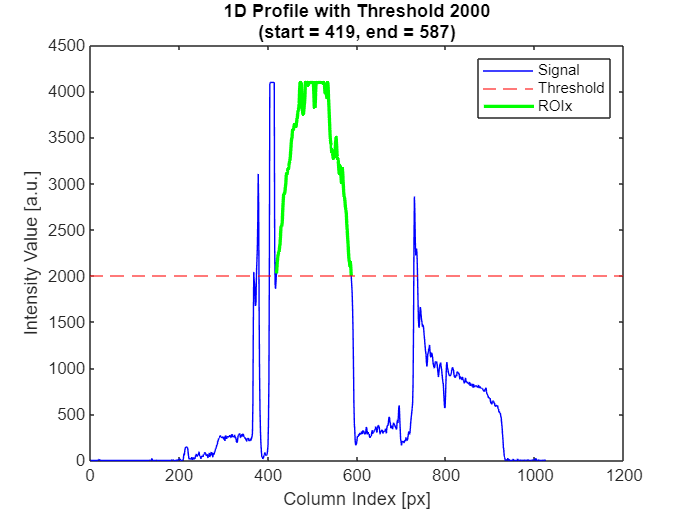


% Plotting
figure;
plot(line, 'b'); hold on;
yline(thr_apple, 'r--');
xlabel('Column Index [px]'); 
ylabel('Intensity Value [a.u.]');

% Highlight detected region
if ~isnan(left_px)
    x = left_px:right_px;
    plot(x, line(x), 'g', 'LineWidth', 2);
    legend('Signal', 'Threshold', 'ROIx');
    title(sprintf('1D Profile with Threshold %d\n(start = %d, end = %d)', thr_apple, left_px, right_px));
else
    title('1D Profile - No Region Detected');
end

## Finding ROIx for one single IMAGE (256x1024)

filename = "test_images/apples_images/Image_75.tiff";
img_raw = imread(filename);

thr_apple = 2000;  % a.u.
min_length = 100;  % px
num_lines = 256;    % number of rows to scan

roi_bounds = NaN(num_lines, 2);  % initialize output matrix

disp('Starting loop over lines...')

Starting loop over lines...


for row_idx = 1:num_lines
    line = img_raw(row_idx, :);  % extract current line
    mask_overthr = line >= thr_apple;

    inside = false;
    left_px = NaN;
    right_px = NaN;
    length_counter = 0;

    for i = 1:length(line)
        if mask_overthr(i)
            if ~inside
                inside = true;
                length_counter = 1;
                temp_left = i;
            else
                length_counter = length_counter + 1;
            end
        else
            if inside
                if length_counter >= min_length
                    left_px = temp_left;
                    right_px = i - 1;
                    break;  % only first region
                end
                inside = false;
                length_counter = 0;
            end
        end
    end

    % Save results in the matrix
    roi_bounds(row_idx, :) = [left_px, right_px];
end
disp('Finished loop over lines.')

Finished loop over lines.



% Filter out rows where either left or right is NaN
%disp('------------------VALID ROIx BOUNDS-------------------');
valid_roi_bounds = roi_bounds(~any(isnan(roi_bounds), 2), :); 
%disp(valid_roi_bounds);

% Averaging over the valid stripes that respect trigger conditions
% (I>2000,t>100)
avg_roi_x1 = 0;
avg_roi_x2 = 0;
sum_roi_x1 = 0;
sum_roi_x2 = 0;
for i=1:length(valid_roi_bounds)
    sum_roi_x1 = sum_roi_x1 + valid_roi_bounds(i,1);
    sum_roi_x2 = sum_roi_x2 + valid_roi_bounds(i,2);
end
avg_roi_x1 = round(sum_roi_x1/length(valid_roi_bounds));
avg_roi_x2 = round(sum_roi_x2/length(valid_roi_bounds));
disp('------------------MEAN ROIx BOUNDS-------------------');

------------------MEAN ROIx BOUNDS-------------------


fprintf('Mean ROIx for image %s is ROIx = (%d,%d)\n', filename, avg_roi_x, avg_roi_y);

Mean ROIx for image test_images/apples_images/Image_75.tiff is ROIx = (467,467)


## Finding ROIx for multiple IMAGES (256x1024xNUM_FILES)

fprintf('\nStart analyzing files...\n')


Start analyzing files...


% Folder path
folder_path = "test_images/apples_images";
image_files = dir(fullfile(folder_path, "*.tiff"));

% DEBUG: list found files
if isempty(image_files)
    error("❌ No .tiff files found in folder: %s\n", folder_path);
else
    fprintf("✅ Found %d .tiff files in folder: %s\n", length(image_files), folder_path);
    disp({image_files.name}');
end

✅ Found 5 .tiff files in folder: test_images/apples_images


    {'Image_69.tiff'}
    {'Image_70.tiff'}
    {'Image_71.tiff'}
    {'Image_75.tiff'}
    {'Image_77.tiff'}




% Set number of lines to analyze per image
num_lines = 256;  % can be changed freely
thr_apple = 2000;
min_length = 100;

% Initialize accumulators for all images
total_avg_roi_x = 0;
total_avg_roi_y = 0;
num_files = length(image_files);  % or set manually if you want fewer

for idx = 1:num_files
    filename = fullfile(image_files(idx).folder, image_files(idx).name);
    img_raw = imread(filename);

    roi_bounds = NaN(num_lines, 2);

    % Loop through each line
    for row_idx = 1:num_lines
        line = img_raw(row_idx, :);
        mask_overthr = line >= thr_apple;

        inside = false;
        left_px = NaN;
        right_px = NaN;
        length_counter = 0;

        for i = 1:length(line)
            if mask_overthr(i)
                if ~inside
                    inside = true;
                    length_counter = 1;
                    temp_left = i;
                else
                    length_counter = length_counter + 1;
                end
            else
                if inside
                    if length_counter >= min_length
                        left_px = temp_left;
                        right_px = i - 1;
                        break;
                    end
                    inside = false;
                    length_counter = 0;
                end
            end
        end

        roi_bounds(row_idx, :) = [left_px, right_px];
    end

    % Filter valid ROI bounds
    valid_roi_bounds = roi_bounds(~any(isnan(roi_bounds), 2), :);

    % Compute mean ROI bounds for this image
    avg_roi_x = round(mean(valid_roi_bounds(:,1)));
    avg_roi_y = round(mean(valid_roi_bounds(:,2)));

    % Accumulate for overall stats
    total_avg_roi_x = total_avg_roi_x + avg_roi_x;
    total_avg_roi_y = total_avg_roi_y + avg_roi_y;

    % Print result for this image
    fprintf('Mean ROIx for image %s is ROIx = (%d,%d)\n', ...
        image_files(idx).name, avg_roi_x, avg_roi_y);
end

Mean ROIx for image Image_69.tiff is ROIx = (437,565)
Mean ROIx for image Image_70.tiff is ROIx = (426,574)
Mean ROIx for image Image_71.tiff is ROIx = (436,562)
Mean ROIx for image Image_75.tiff is ROIx = (467,581)
Mean ROIx for image Image_77.tiff is ROIx = (NaN,NaN)



% Final mean over all images
avg_roi_x_all = round(total_avg_roi_x / num_files);
avg_roi_y_all = round(total_avg_roi_y / num_files);

fprintf('\nGLOBAL MEAN ROIx across %d images: (%d, %d)\n', ...
    num_files, avg_roi_x_all, avg_roi_y_all);


GLOBAL MEAN ROIx across 5 images: (NaN, NaN)



fprintf('Analysis completed.\n---------------------------------------------\n')

Analysis completed.
---------------------------------------------


## Visualize CENTER LINES plots for MULTIPLE IMAGES

function show_center_lines(selection)
    % === PARAMETERS ===
    folder_path = "test_images/apples_images";
    thr_apple = 2000;
    min_length = 100;

    % Load image list
    image_files = dir(fullfile(folder_path, "*.tiff"));
    if isempty(image_files)
        error("❌ No .tiff files found in folder: %s\n", folder_path);
    end

    if ischar(selection)
        selection = string(selection);
    end

    for idx = 1:length(image_files)
        filename = image_files(idx).name;

        if any(strcmp(selection,"all")) || any(strcmp(selection,filename))
            full_path = fullfile(image_files(idx).folder, filename);
            img = imread(full_path);

            % Central row
            central_row = round(size(img, 1) / 2);
            line = img(central_row, :);
            mask = line >= thr_apple;

            % ROI detection
            inside = false;
            left_px = NaN;
            right_px = NaN;
            length_counter = 0;

            for i = 1:length(line)
                if mask(i)
                    if ~inside
                        inside = true;
                        length_counter = 1;
                        temp_left = i;
                    else
                        length_counter = length_counter + 1;
                    end
                else
                    if inside
                        if length_counter >= min_length
                            left_px = temp_left;
                            right_px = i - 1;
                            break;
                        end
                        inside = false;
                        length_counter = 0;
                    end
                end
            end

            % === PLOT ===
            figure;
            plot(line, 'b'); hold on;
            yline(thr_apple, 'r--', 'Threshold');

            if ~isnan(left_px)
                x = left_px:right_px;
                plot(x, line(x), 'g', 'LineWidth', 2);
                legend('Center line', 'Threshold', ...
                       sprintf('ROIx [%d:%d]', left_px, right_px), ...
                       'Location', 'best');
                title(sprintf('%s - Line %d\nROI = [%d, %d]', ...
                      filename, central_row, left_px, right_px), ...
                      'Interpreter', 'none');
            else
                legend('Center line', 'Threshold', ...
                       'Location', 'best');
                title(sprintf('%s - Line %d\nNo ROI found', ...
                      filename, central_row), ...
                      'Interpreter', 'none');
            end

            xlabel('Column Index [px]');
            ylabel('Intensity [a.u.]');
        end
    end
end

%{
    //////////////////////////////////////////////////
    /                   MAIN                         /
    //////////////////////////////////////////////////
%}

%show_center_lines("Image_75.tiff");  % solo una immagine
show_center_lines(["Image_77.tiff", "Image_69.tiff"]);  % più immagini
%show_center_lines("all");  % tutte le immagini nella cartella